## Лабораторная работа 3. 

## Настройка регулятора по звеньям

**Студент:** Ларченков Артем Алексеевич

**ИСУ:** 369936

**Вариант:** 1

**Робот:** Fanuc10L

close all
clear all
clc

### 1)  Загружаем модель робота и задаем параметры

% Создание модели робота
mdl_fanuc10L % Загружаем модель робота Fanuc 10L
mdl_puma560; % Загружаем модель робота Puma 560
J_link = zeros(3,3);
rad = 0.05;
% Массы звеньев
R.links(1, 1).m = 10;
R.links(1, 2).m = 8;
R.links(1, 3).m = 8;
R.links(1, 4).m = 5;
R.links(1, 5).m = 4;
R.links(1, 6).m = 2

 
R = 
 
Fanuc AM120iB/10L:: 6 axis, RRRRRR, stdDH, slowRNE               
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|       0.15|    -1.5708|          0|
|  2|         q2|          0|       0.77|    3.14159|          0|
|  3|         q3|          0|        0.1|    -1.5708|          0|
|  4|         q4|      -0.96|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|       -0.1|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 



% Центры масс звеньев
%  центры масс для каждого звена
R.links(1,1).r = [R.links(1,1).a/2, 0, R.links(1,1).d/2]; 
R.links(1,2).r = [0.06491, -0.13089, 0.02913]; 
R.links(1,3).r = [-0.00973, -0.16171, 0.09243]; 
R.links(1,4).r = [-0.00089, -0.00867, -0.13649]; 
R.links(1,5).r = [-0.04077, 0, 0]; 
R.links(1,6).r = [-0.0000602, -0.0004162, -0.0486737]; 

%  константы двигателя для каждого звена
torq_const(1) = 0.253; 
torq_const(2) = 0.253; 
torq_const(3) = 0.253;  
torq_const(4) = 0.095; 
torq_const(5) = 0.095; 
torq_const(6) = 0.095; 

% максимальный момент для каждого звена
torq_max(1) = 50; 
torq_max(2) = 40; 
torq_max(3) = 33;  
torq_max(4) = 20; 
torq_max(5) = 10; 
torq_max(6) = 5; 


% Задаем момент инерции, моменты инерции валов приводов, трение и передаточное число для Fanuc 10L аналогичных Puma 560
for i = 1:1:6
    R.links(1,i).I = p560.links(1,i).I;
    R.links(1,i).Jm = p560.links(1,i).Jm;
    R.links(1,i).G = p560.links(1,i).G;
    R.links(1,i).B = p560.links(1,i).B;    
end

### 2)  Настроим генератор траектории

q_start = [0,0,0,0,0,pi] % Задаем начальное положение робота

q_start =          0         0         0         0         0    3.1416


point = [0.5,0.5,0.5]; % Выбираем конечную точку из рабочего пространства робота
q_end = R.ikine(transl(point)*trotx(pi/5)) % Решаем ОЗК для конечного положения

q_end =     0.7843   -2.1283   -0.7167   -0.0079   -1.4039   -0.7830


stop_time = 5; % Задаем время симуляции
% gen_traject % Запускаем модель генератора траекторий

### 3)  Рассчитаем инерцию каждого звена манипулятора

chislotochek = 5; % Задаем число точек для расчета матриц масс

% Задаем сетки и пустые массивы для дальнейших расчетов
QQ2 = linspace(R.qlim(2,1),R.qlim(2,2),chislotochek);
QQ3 = linspace(R.qlim(3,1),R.qlim(3,2),chislotochek);
QQ4 = linspace(R.qlim(4,1),R.qlim(4,2),chislotochek);
M11bez = zeros(chislotochek,chislotochek); M22bez = zeros(chislotochek,chislotochek);
M33bez = zeros(chislotochek,chislotochek); M44bez = zeros(chislotochek,chislotochek);
M55bez = zeros(chislotochek,chislotochek); M66bez = zeros(chislotochek,chislotochek);
[Q2,Q3,Q4] = meshgrid(QQ2, QQ3, QQ4);

% Определяем возможные значения матрицы масс вдоль заданной траектории для каждого звена 
for i=1:numcols(Q2)
    for j=1:numcols(Q3)
        for k=1:numcols(Q4)
            Mbez = R.inertia([0, Q2(i,j,k), Q3(i,j,k), Q4(i,j,k), 0, 0]);
            M11bez(j,k) = Mbez(1,1);
            M22bez(j,k) = Mbez(2,2);
            M33bez(j,k) = Mbez(3,3);
            M44bez(j,k) = Mbez(4,4);
            M55bez(j,k) = Mbez(5,5);
            M66bez(j,k) = Mbez(6,6);
        end    
    end
end

% Находим средние значения матриц масс для каждого звена
Meanbez(1) = mean(M11bez,'all');
Meanbez(2) = mean(M22bez,'all');
Meanbez(3) = mean(M33bez,'all');
Meanbez(4) = mean(M44bez,'all');
Meanbez(5) = mean(M55bez,'all');
Meanbez(6) = mean(M66bez,'all');

% Определим отношение максимального и минимального элементов
% матриц масс при движении вдоль заданной траектории
otnbez = zeros(1,6);
otnbez(1) = max(M11bez(:))/min(M11bez(:));
otnbez(2) = max(M22bez(:))/min(M22bez(:));
otnbez(3) = max(M33bez(:))/min(M33bez(:));
otnbez(4) = max(M44bez(:))/min(M44bez(:));
otnbez(5) = max(M55bez(:))/min(M55bez(:));
otnbez(6) = max(M66bez(:))/min(M66bez(:));
otnbez

otnbez =     2.2567    1.0667    1.0233    1.0000    1.0000    1.0000



% Вычисляем инерцию каждого звена
InertiaA = zeros(1,6);
for i=1:6
    InertiaA(i) = R.links(1,i).Jm + Meanbez(i)/(R.links(1,i).G^2)
end

InertiaA =     0.0039         0         0         0         0         0


InertiaA =     0.0039    0.0026         0         0         0         0


InertiaA =     0.0039    0.0026    0.0043         0         0         0


InertiaA =     0.0039    0.0026    0.0043    0.0001         0         0


InertiaA =     0.0039    0.0026    0.0043    0.0001    0.0001         0


InertiaA =     0.0039    0.0026    0.0043    0.0001    0.0001    0.0001


#### 4) Настроим контуры управления по скорости и положению без нагрузки

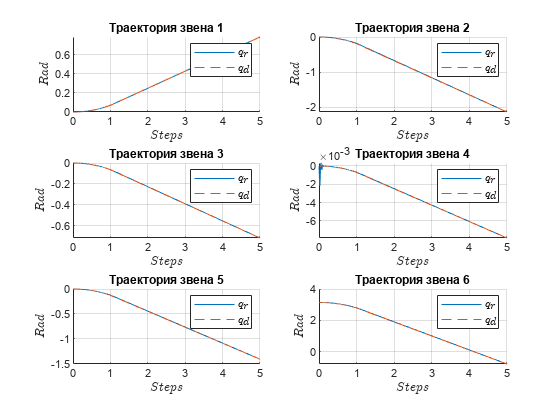

% vloop_no_load % Запускаем контур управления по скорости
ploop_no_load % Запускаем контур управления по положению

NL = sim("ploop_no_load.slx"); % Выполняем симуляцию

% Построим графики реальной (r) траектории движения и желаемой (d) для каждого звена
figure; 
for i=1:1:6
    subplot(3,2,i)
    hold on
    plot(NL.THETA.time, NL.THETA.data(:,i), NL.Q.time, NL.Q.data(:,i), '--')
    grid on
    legend('$q_r$', '$q_d$', 'fontsize', 9,'interpreter','latex');
    ylabel('$Rad$', 'fontsize', 10, 'interpreter', 'latex');
    xlabel('$Steps$', 'fontsize', 10, 'interpreter', 'latex');
    title(['Траектория звена ', num2str(i)]);
end

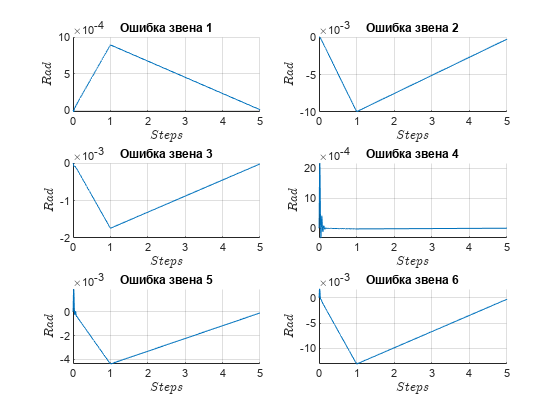

figure; % Построим графики ошибок для каждого звена
for i=1:1:6
    subplot(3,2,i)
    hold on
    plot(NL.ERR.time, NL.ERR.data(:,i))
    grid on
    ylabel('$Rad$', 'fontsize', 10, 'interpreter', 'latex');
    xlabel('$Steps$', 'fontsize', 10, 'interpreter', 'latex');
    title(['Ошибка звена ', num2str(i)]);
end

#### 5) Добавим нагрузку и пересчитаем инерцию каждого звена 

R.payload(5,[0,0,0.1]); % Добавляем нагрузку 5 кг 

% Задаем пустые массивы для дальнейших вычислений
M11s = zeros(chislotochek,chislotochek); M22s = zeros(chislotochek,chislotochek);
M33s = zeros(chislotochek,chislotochek); M44s = zeros(chislotochek,chislotochek);
M55s = zeros(chislotochek,chislotochek); M66s = zeros(chislotochek,chislotochek);

% Определяем возможные значения матрицы масс вдоль заданной траектории для каждоого звена 
for i=1:numcols(Q2)
    for j=1:numcols(Q3)
        for k=1:numcols(Q4)
            Ms = R.inertia([0, Q2(i,j,k), Q3(i,j,k), Q4(i,j,k), 0, 0]);
            M11s(j,k) = Ms(1,1);
            M22s(j,k) = Ms(2,2);
            M33s(j,k) = Ms(3,3);
            M44s(j,k) = Ms(4,4);
            M55s(j,k) = Ms(5,5);
            M66s(j,k) = Ms(6,6);
        end    
    end
end

% Находим средние значения матриц масс для каждого звена
Means(1) = mean(M11s,'all');
Means(2) = mean(M22s,'all');
Means(3) = mean(M33s,'all');
Means(4) = mean(M44s,'all');
Means(5) = mean(M55s,'all');
Means(6) = mean(M66s,'all');

% Вычисляем инерцию каждого звена
InertiaS = zeros(1,6);
for i=1:6
    InertiaS(i) = R.links(1,i).Jm + Means(i)/(R.links(1,i).G^2)
end

InertiaS =     0.0044         0         0         0         0         0


InertiaS =     0.0044    0.0029         0         0         0         0


InertiaS =     0.0044    0.0029    0.0050         0         0         0


InertiaS =     0.0044    0.0029    0.0050    0.0001         0         0


InertiaS =     0.0044    0.0029    0.0050    0.0001    0.0001         0


InertiaS =     0.0044    0.0029    0.0050    0.0001    0.0001    0.0001



% Определим отношение максимального и минимального элементов
% матриц масс при движении вдоль заданной траектории
otn(1) = max(M11s(:))/min(M11s(:));
otn(2) = max(M22s(:))/min(M22s(:));
otn(3) = max(M33s(:))/min(M33s(:));
otn(4) = max(M44s(:))/min(M44s(:));
otn(5) = max(M55s(:))/min(M55s(:));
otn(6) = max(M66s(:))/min(M66s(:));
otn

otn =     2.2731    1.0592    1.0197    1.0000    1.0000    1.0000


### 6) Перенастроим контуры управления по скорости и положению

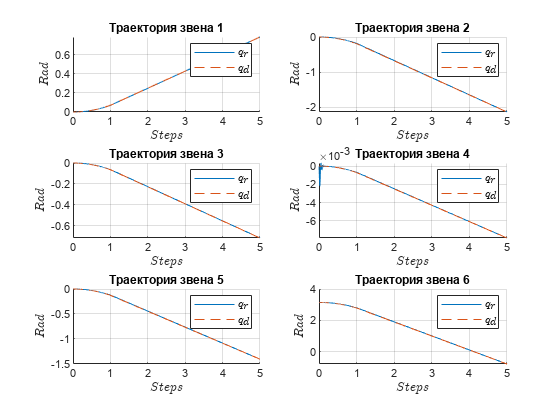

% vloop_load % Запускаем контур управления по скорости
ploop_load % Запускаем контур управления по положению

WL = sim("ploop_load.slx"); % Выполняем симуляцию

% Построим графики реальной (r) траектории движения и желаемой (d) для каждого звена
figure; 
for i=1:1:6
    subplot(3,2,i)
    hold on
    plot(WL.THETA.time, WL.THETA.data(:,i), WL.Q.time, WL.Q.data(:,i), '--')
    grid on
    legend('$q_r$', '$q_d$', 'fontsize', 9,'interpreter','latex');
    ylabel('$Rad$', 'fontsize', 10, 'interpreter', 'latex');
    xlabel('$Steps$', 'fontsize', 10, 'interpreter', 'latex');
    title(['Траектория звена ', num2str(i)]);
end

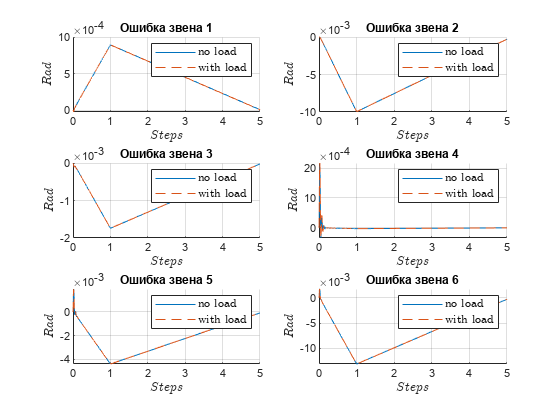

figure; % Сравним графики ошибок для каждого звена
for i=1:1:6
    subplot(3,2,i)
    hold on
    plot(NL.ERR.time, NL.ERR.data(:,i), WL.ERR.time, WL.ERR.data(:,i), '--')
    grid on
    legend('no load', 'with load', 'fontsize', 9,'interpreter','latex');
    ylabel('$Rad$', 'fontsize', 10, 'interpreter', 'latex');
    xlabel('$Steps$', 'fontsize', 10, 'interpreter', 'latex');
    title(['Ошибка звена ', num2str(i)]);
end

#### Выводы: 

В ходе данной лабораторной работы были выполнены следующие задачи:

1) Рассчитаны матрицы масс и инерции каждого звена для робота с нагрузкой и без: при добавлении нагрузки матрица масс и инреции звеньев изменяются, однако, соотношение максимального и минимального элементов матрицы масс остается прежним;

2) Подобраны коеффициенты ПИ-регулятора контура управления по скорости для каждого звена

3) Подобраны коеффициенты $K_P$ контура управления по положению для каждого звена

5) Для робота с нагрузкой и без для каждого звена построены графики реальной и желаемой траекторий, а также графики ошибок

6) Не все звенья четко следуют по желаемой траектории, но такого добиться возможно, лучше настроив регуляторы.

4) При добавлении нагрузки в 10 кг ошибка увеличивается, однако она остается небольшой. 